# Calculate Contact Stiffness

## Circular Contact

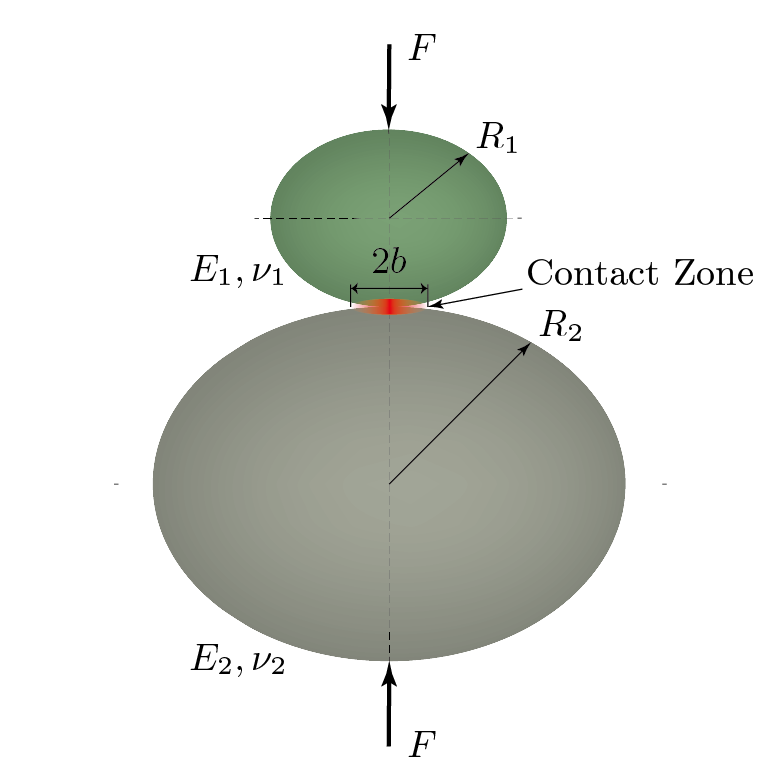

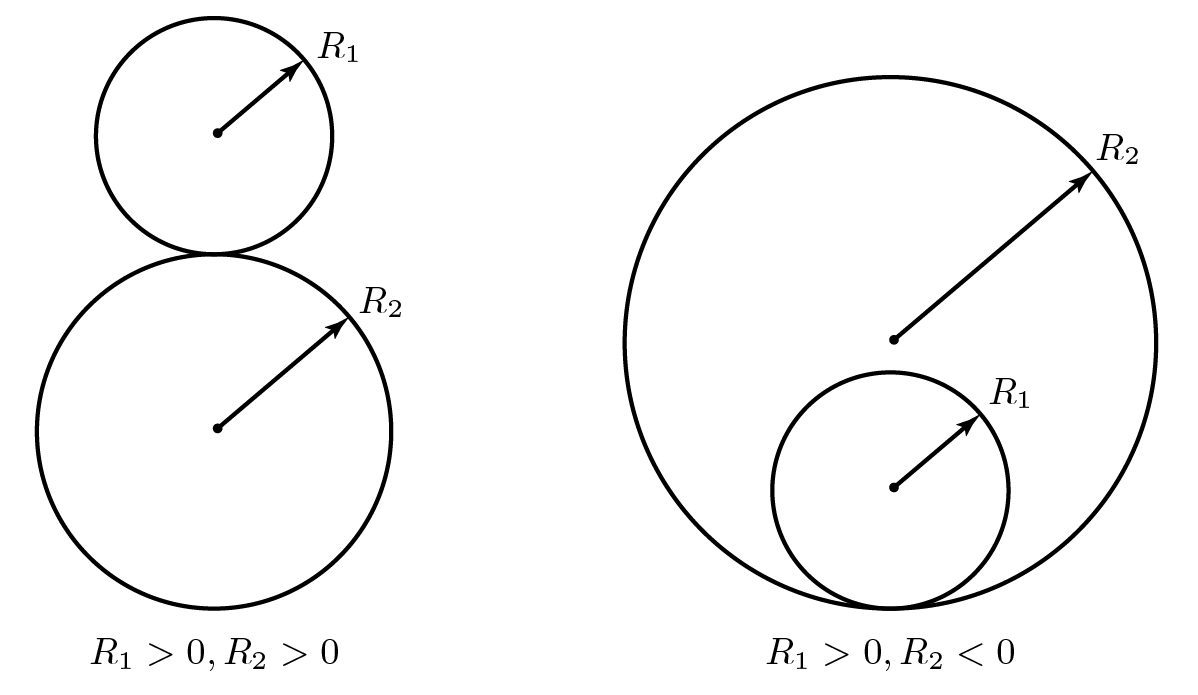

### Symbols

$\delta$: distance between two spheres

$E_i,\nu_i$: the  elastic modulus and Poisson's ratio for the i-th sphere

$R_i$: the radius of the i-th sphere

$F$: force on spheres

$b$: the half width of contact

$E^*$: the combined modulus of two spheres

$R^*$: reciprocal of relative curvature for two spheres

### Equations


$${\delta}^3=
\left(\frac{3}{4E^*}\right)^2 
\frac{F^2}{R^*}$$
 


$$F = \left( \frac{4E^*\sqrt{R^*}}{3} \right) \delta^\frac{3}{2}=k_{\mathrm{Hertz}} \; \delta^\frac{3}{2}$$



$$\frac{1}{E^*} 
= \frac{(1-\nu_1^2)}{E_1}
+ \frac{(1-\nu_2^2)}{E_2}$$



$$\frac{1}{R^*}
= \frac{1}{R_1} + \frac{1}{R_2}$$


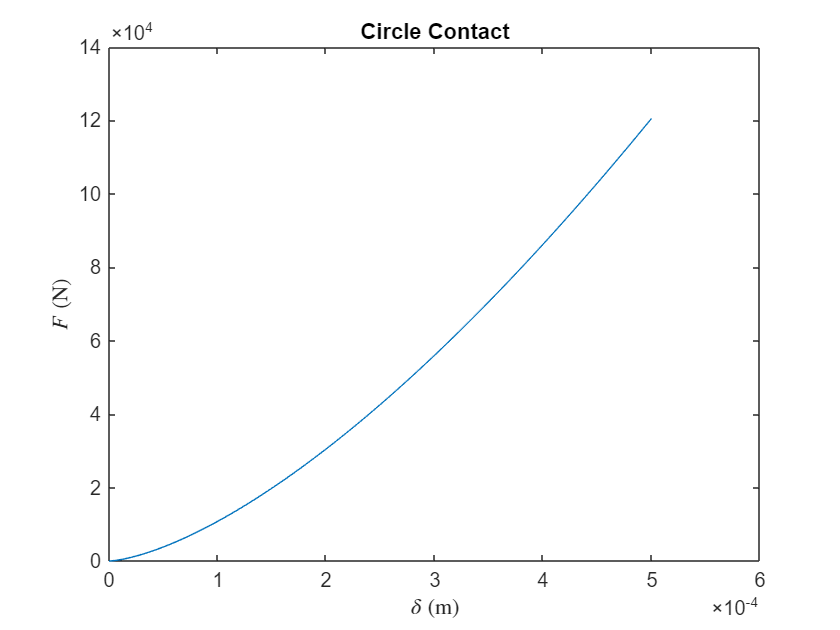

clc
clear
close all
% choose the bearing to calculte contact stiffness
bearingType = 6204;
switch bearingType
    case 6204
        % SKF 6204 bearing
        % Physics parameters
        E1 = 210e9; % elastic modulus (Pa)
        nu1 = 0.3; % poison's ratio
        E2 = E1;
        nu2 = nu1;
        % Geometrics parameters
        R1 = 3.97e-3; % radius of sphere 1 (m)
        R2 = -20.7e-3;
        disRange = 5e-4; % clearance + deformation
    case 6212
        % SKF 6212 bearing
        % Physics parameters
        E1 = 210e9; % elastic modulus (Pa)
        nu1 = 0.3; % poison's ratio
        E2 = E1;
        nu2 = nu1;
        % Geometrics parameters
        R1 = 7.94e-3; % radius of sphere 1 (m)
        R2 = -50.43e-3;
        disRange = 6e-4; % clearance + deformation
end


% calculated parameters
Ec = ((1-nu1^2)/E1 + (1-nu2^2)/E2)^-1; % combined modulus
Rc = (1/R1 + 1/R2)^-1;
kHertz = 4/3 * (Ec*Rc^(1/2));

% Force and displacement
num = 1000;
delta = linspace(0,disRange,num);
FCircle = kHertz * delta.^(3/2);

% plot delta-F
plot(delta,FCircle)
xlabel('$\delta$ (m)','Interpreter',"latex")
ylabel('$F$ (N)','Interpreter',"latex")
title('Circle Contact')

fprintf('kHertz = %d', kHertz);

kHertz = 1.078249e+10

## Line Contact

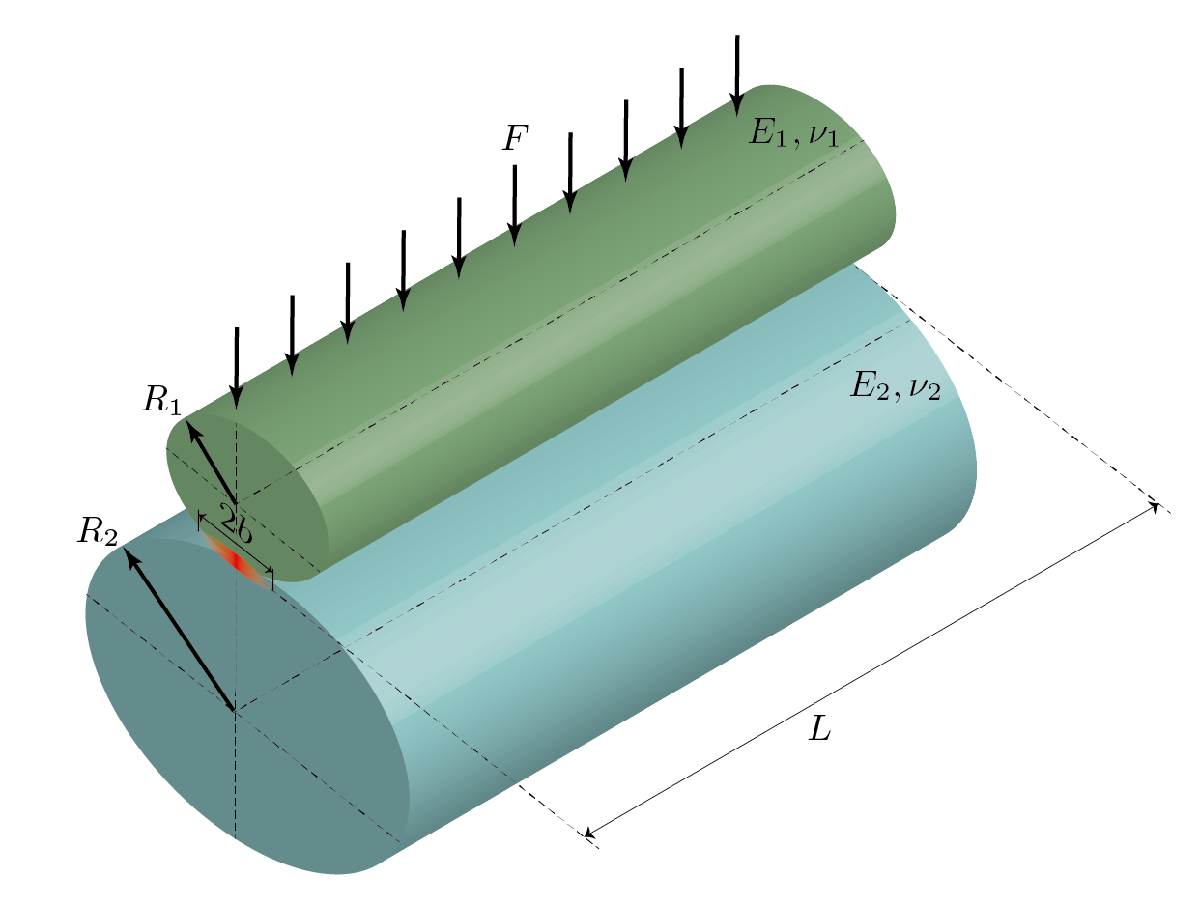

### Symbols

$\delta$: distance between two cylinders

$E_i,\nu_i$: the  elastic modulus and Poisson's ratio for the i-th cylinder

$R_i$: the radius of the i-th cylinder

$F$: force on cylinders

$b$: the half width of contact

$E^*$: the combined modulus of two cylinders

$R^*$: reciprocal of relative curvature for two cylinders

$L$: the length of the contact area

### Equations (Radzimovsky Model)


$$\delta
= \frac{F}{\pi LE^*} 
\left( \ln{\frac{4R_1}{b}} 
+ \ln{\frac{4R_2}{b}} 
+ \frac{2}{3}\right)$$



$$b 
= 2 \sqrt{\frac{FR^*}{\pi L E^*}}$$



$$\frac{1}{E^*} 
= \frac{(1-\nu_1^2)}{E_1}
+ \frac{(1-\nu_2^2)}{E_2}$$



$$\frac{1}{R^*}
= \frac{1}{R_1} + \frac{1}{R_2}$$


% the physics and geometrics parameters are same as circle contact
L = 4*R1; % the length of contact

b = @(F) 2*((F*Rc)/(pi*L*Ec)).^(1/2); % half width of contact
% nonlinear funciton respect to F (Radzimovsky model)
fdeltaRadzi = @(F) F./(pi*L*Ec) .*(log(4*abs(R1)./b(F))+log(4*abs(R2)./b(F)+2/3));

% solve nonlinear equation to cauculat F
% FRadzi = zeros(1,num);
% F0 = 1;
% for iDelta=1:1:num
%     equation = @(F) fdeltaRadzi(F) - delta(iDelta);
%     FRadzi(iDelta) = fsolve(equation,F0);
%     % F0 = FRadzi(iDelta);
% end

### Equations (Johnson's Model)

There is another model called Johnson's model


$$\delta(F) 
= \delta_1(F) + \delta_2(F)$$



$$\delta_i(F)
= \frac{F(1-\nu_i^2)}{\pi L E_i} 
\left( 2 \ln{\frac{4R_1}{b} - 1} \right)$$
 


$$b 
= 2 \sqrt{\frac{FR^*}{\pi L E^*}}$$


Consider $E_1 = E_2 = E,\; R_1 = R_2 =R$, the above equations could be simplified:


$$\delta
= \delta_1 + \delta_2
= \frac{2F(1-\nu^2)}{\pi LE} 
\left( \ln{\frac{4R_1}{b}} 
+ \ln{\frac{4R_2}{b}} 
- 1\right)$$


As Pereira said "Only the Johson and the Radzimovsky models are suitable to describe the contact involving colliding cylinders in most of practical applications."

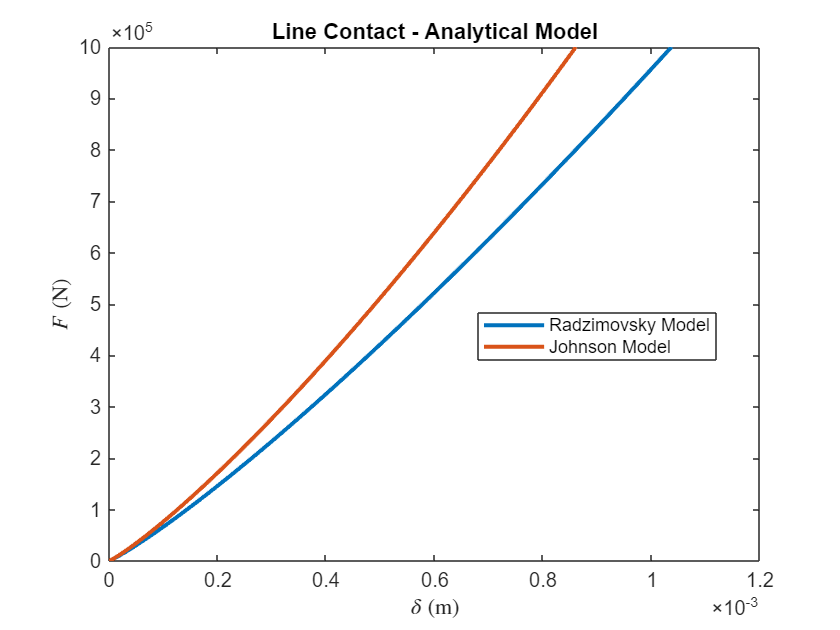

% nonlinear funciton respect to F (Johnson model)
fdeltaJohnsoni = @(F,nu,E,R) F.*(1-nu^2)/(pi*L*E) .* (2*log(4*abs(R)./b(F)) - 1);
fdeltaJohnson = @(F,nu1,E1,R1,nu2,E2,R2) fdeltaJohnsoni(F,nu1,E1,R1) + fdeltaJohnsoni(F,nu2,E2,R2);

% calculte relation
F = linspace(0.1,1e6,num);
deltaRadzi = fdeltaRadzi(F);
deltaJohnson = fdeltaJohnson(F,nu1,E1,R1,nu2,E2,R2);

% plot
plot(deltaRadzi, F, "LineWidth",2); hold on
plot(deltaJohnson, F, "LineWidth",2)
xlabel('$\delta$ (m)','Interpreter',"latex")
ylabel('$F$ (N)','Interpreter',"latex")
title('Line Contact - Analytical Model')
legend('Radzimovsky Model','Johnson Model',"Location","best")
hold off

### Polynomial Interpolation

In general, we used to use a approximate polynomial to fit the nonlinear equation about the line contact. 

The polynomial looks like:


$$F=k_{Hertz} \; \delta^n$$


where $n=10/9$ for line contact.

% initial value for fit
n = 10/9;
k0 = 1e10; 
n0 = 1; 
% fitfun1(): k is unknown
fitfun1 = @(k,delta) k.*delta.^n; % n = 9/10
% fitfun2(): k and n are unknown
fitfun2 = @(para,delta) para(1).*delta.^para(2); % para is established for nlinfit()


% fit for Radzimovasky model
% fitfun1
[kRadzi1, ~,~,~,MSERadzi1,~] = nlinfit(deltaRadzi, F, fitfun1, k0); 
% fitfun2
[fitParaResult, ~,~,~,MSERadzi2,~] = nlinfit(deltaRadzi, F, fitfun2, [k0, n0]); 

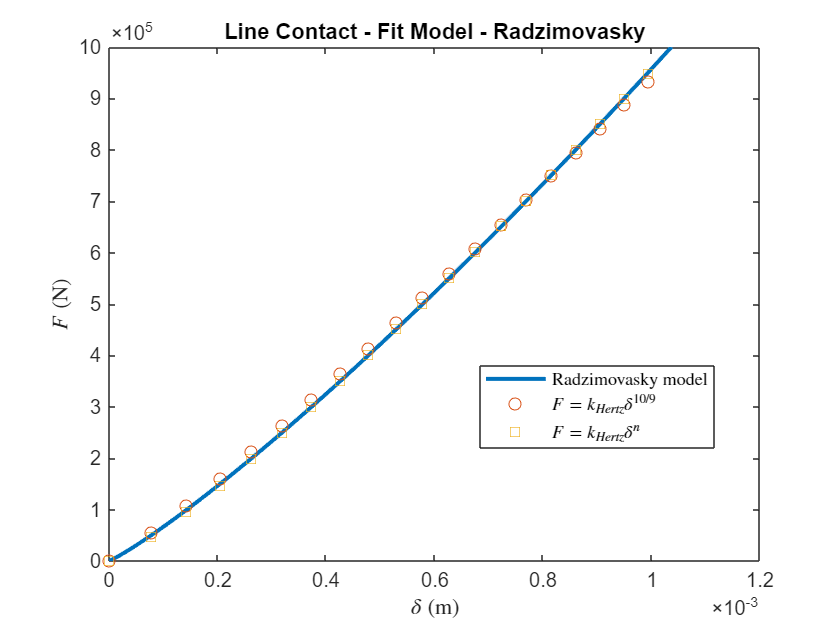

kRadzi2 = fitParaResult(1);
nRadzi2 = fitParaResult(2); 
% plot for Radzimovasky model
plot(deltaRadzi,F,...
     "LineWidth",2); hold on
plot(deltaRadzi,fitfun1(kRadzi1,deltaRadzi),...
     'o',...
     'MarkerIndices', 1:num/20:num); hold on
plot(deltaRadzi,fitfun2([kRadzi2,nRadzi2],deltaRadzi),...
     's',...
     'MarkerIndices', 1:num/20:num); hold off
xlabel('$\delta$ (m)','Interpreter',"latex")
ylabel('$F$ (N)','Interpreter',"latex")
title('Line Contact - Fit Model - Radzimovasky')
legend( 'Radzimovasky model',...
        '$F = k_{Hertz} \delta^{10/9}$',...
        '$F = k_{Hertz} \delta^n$',...
        'Interpreter',"latex",...
        "Location","best")

% print fit result
fprintf(['       k unknow  k and n unknow\n' ...
         'n      %6.6f  %6.6f\n'...
         'KHertz %6.2e  %6.2e\n'...
         'MSE    %6.2e  %6.2e'],...
         n, nRadzi2,...
         kRadzi1, kRadzi2,...
         MSERadzi1, MSERadzi2); 

       k unknow  k and n unknow
n      1.111111  1.177467
KHertz 2.02e+09  3.26e+09
MSE    1.23e+08  2.36e+06

% fit for Johnson model
% fitfun1
[kJohnson1, ~,~,~,MSEJohnson1,~] = nlinfit(deltaJohnson, F, fitfun1, k0); 
% fitfun2
[fitParaResult, ~,~,~,MSEJohnson2,~] = nlinfit(deltaJohnson, F, fitfun2, [k0, n0]); 

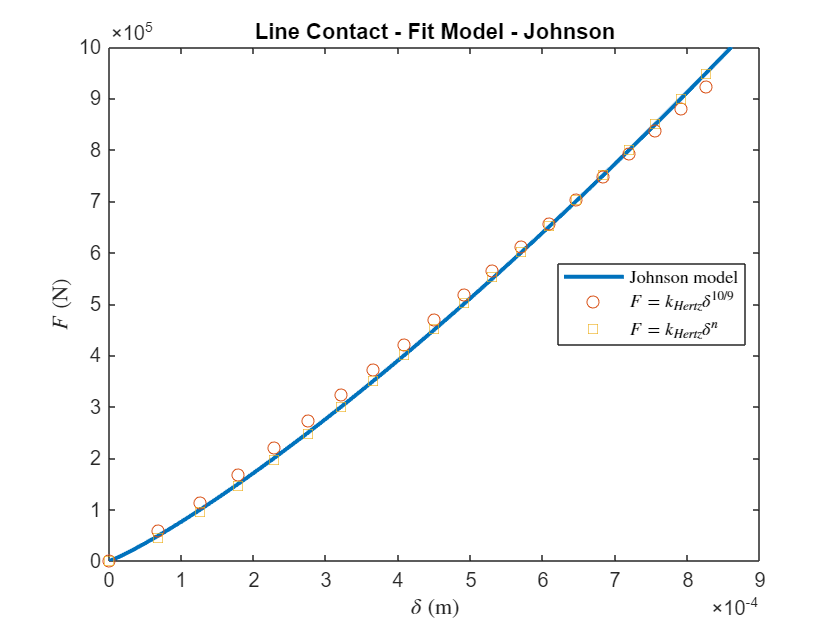

kJohnson2 = fitParaResult(1);
nJohnson2 = fitParaResult(2); 
% plot for Radzimovasky model
plot(deltaJohnson,F,...
     "LineWidth",2); hold on
plot(deltaJohnson,fitfun1(kJohnson1,deltaJohnson),...
     'o',...
     'MarkerIndices', 1:num/20:num); hold on
plot(deltaJohnson,fitfun2([kJohnson2,nJohnson2],deltaJohnson),...
     's',...
     'MarkerIndices', 1:num/20:num); hold off
xlabel('$\delta$ (m)','Interpreter',"latex")
ylabel('$F$ (N)','Interpreter',"latex")
title('Line Contact - Fit Model - Johnson')
legend( 'Johnson model',...
        '$F = k_{Hertz} \delta^{10/9}$',...
        '$F = k_{Hertz} \delta^n$',...
        'Interpreter',"latex",...
        "Location","best")

% print fit result
fprintf(['       k unknow  k and n unknow\n' ...
         'n      %6.6f  %6.6f\n'...
         'KHertz %6.2e  %6.2e\n'...
         'MSE    %6.2e  %6.2e'],...
         n, nJohnson2,...
         kJohnson1, kJohnson2,...
         MSEJohnson1, MSEJohnson2); 

       k unknow  k and n unknow
n      1.111111  1.218264
KHertz 2.46e+09  5.40e+09
MSE    3.03e+08  5.03e+06

## Reference

[1] Hale, Layton C. Appendix C: Contact Mechanics, in "Principles and techniques for desiging precision machines." MIT PhD Thesis, 1999. pp. 417-426. 

[2] K. L. Johnson, “Non-Hertzian normal contact of elastic bodies,” in *Contact Mechanics*, Cambridge: Cambridge University Press, 1985, pp. 107–152.

[3] A. C. Fischer-Cripps, "Elastic Contact," In *Introduction to Contact Mechanics. Mechanical Engineering Series,* Boston: Springer, 2007, pp. 101-114.

[4] Cândida M. Pereira, Amílcar L. Ramalho, Jorge A. Ambrósio. A critical overview of internal and external cylinder contact force models. Nonlinear Dynamics, 2010, 63 (4), pp.681-697.

[5] Some slids in web: [Microsoft PowerPoint - Topic2-FundamentalsOfErrors.ppt (utah.edu)](https://my.mech.utah.edu/~me7960/lectures/Topic2-FundamentalsOfErrors.pdf)